# Connecting paths method (CP) 

Hailemariam A. Tekile

5 January 2022

Missing  elements $a_{\textrm{ij}}$ of the  incomplete matrix A  are obtained by taking the geometric mean of intensities of all connecting paths ${\textrm{CP}}_{\textrm{ij}}$ connecting the two alternatives i and j in A; i.e.,


$$a_{\textrm{ij}} =$$

$${\left\lbrack \prod_{s=1}^N {{\left({\textrm{CP}}_{\textrm{ij}} \right)}_s } \right\rbrack }^{\frac{1}{N}}$$


where $N$ is the number of  connecting paths.

**Remarks**: 

1) The interval [1/9,9] has been taken into account. That is, if the stimated value $a_{\textrm{ij}}$ is out of the interval  [1/9,9], readjustment of $a_{\textrm{ij}}$  will be made by considering: if $a_{\textrm{ij}} >\;9,\textrm{then}\;a_{\textrm{ij}} =9;\;\textrm{elseif}\;a_{\textrm{ij}} <\frac{1}{9}$, then $a_{\textrm{ij}} =\frac{1}{9}$ ; else $a_{\textrm{ij}} \;\textrm{itself}\ldotp$

2) ` When matrix size becomes large, the number of connecting paths will be very large (e.g., with n=8 and 3 missing comparisons, we can have 1064 connecting paths - see the output below). Furthermore, in the literature (` Chen, Q., & Triantaphyllou, E. (2001)`), this condition is mentioned as "a drawback of the method". i.e., "for a comparison matrix of dimension of ten, the number of possible connecting paths to be considered might be equal equal to 109,600".`

**References:**

- Tekile, H. A., Brunelli, M., & Fedrizzi, M. (2023). A numerical comparative study of completion methods for pairwise comparison matrices. *Operations Research Perspectives*, 100272.

-  Chen, Q., & Triantaphyllou, E. (2001). Estimating Data for Multicriteria Decision Making Problems. *Optimization Techniques. Encyclopedia of Optimization*, 567-576.

clear; clc
global A;


format short 
% Example 1
% incomplete matrix - 0 indicates the missing entry;
A = [...
    1   3   1/2 2 1/9   2 1/2 2;...
    1/3 1   4   1 1/4 1 1/4 1;...
    2   1/4 1   4 1   4 1   4;...
    1/2 1   1/4 1 1/4 8 1/4 1;...
    9   4   1   4 1   4 1   4;...
    1/2 1   1/4 1/8 1/4 1 1/4 1/7;...
    2   4   1   4 1   4 1   0;...
    1/2 1   1/4 1 1/4 7 0   1];

% 
n = size(A,1); % order of A
% M = A; % to write Missing Values

% position of missing entries
index = 1; % an index that verifies the position of i and j
for j = 2:n % for i < j
    for i = 1:j-1
        if A(i,j) == 0
            xPosition(index,1) = i; % position of x in the ith row
            xPosition(index,2) = j; % position of x in the jth column
            index = index+1; % update index until (A(i,j) == 0) ends
        end
    end
end
xPosition % missing entris position

xPosition =      7     8



% To write Estimated Missing values (incomplete entries position)
MissingValues =  num2cell([xPosition],2)

MissingValues = 1×1 cell array
    {[7 8]}


disp('The  Missing Values in cell array form:')

The  Missing Values in cell array form:


MissingValues

MissingValues = 1×1 cell array
    {[7 8]}


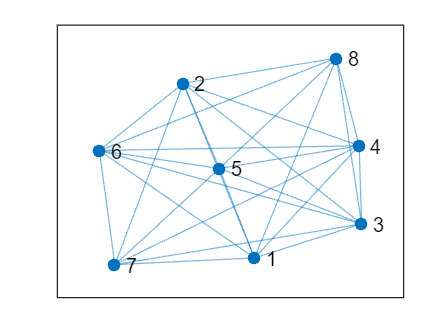

paths = 1956×1 cell array
    {[7 1 2 3 4 5 6 8]}
    {[  7 1 2 3 4 5 8]}
    {[7 1 2 3 4 6 5 8]}
    {[  7 1 2 3 4 6 8]}
    {[    7 1 2 3 4 8]}
    {[7 1 2 3 5 4 6 8]}
    {[  7 1 2 3 5 4 8]}
    {[7 1 2 3 5 6 4 8]}
    {[  7 1 2 3 5 6 8]}
    {[    7 1 2 3 5 8]}
    {[7 1 2 3 6 4 5 8]}
    {[  7 1 2 3 6 4 8]}
    {[7 1 2 3 6 5 4 8]}
    {[  7 1 2 3 6 5 8]}
    {[    7 1 2 3 6 8]}
    {[      7 1 2 3 8]}


The number of  connecting paths is: 


ans = 1956

all possible connecting paths value in a vector form is:


ConnectingPath = 1.0e+03 *

    0.0137    0.0960    0.7680    0.1097    0.0960    0.1097    0.0960    0.0120    0.0137    0.0960    0.0120    0.0120    0.0960    0.0960    0.0137    0.0960    0.0009    0.0060    0.0060    0.0009    0.0060    0.0009    0.0060    0.0060    0.0009    0.0060    0.0480    0.0480    0.0480    0.0480    0.0069    0.0060    0.0069    0.0060    0.0008    0.0009    0.0060    0.0009    0.0060    0.0480    0.0069    0.0060    0.0060    0.0060    0.0008    0.0008    0.0009    0.0060    0.0060    0.0060


ConnectingPath_ij = 2.8921

The final estimated value of A(i,j):


a_ij = 2.8921


% To find the missing values in the position (i,j)
MV = {}; % empty
if  isempty(MV)
MV = MissingValues;
    index = 1; %index
    % for every (i,j) in MissingValue
    for k = 1:length(MV)
        i = MV{k}(1); % row of MissingValue
        j = MV{k}(2); % column of MissingValue
        MV{index} = ConnetingPathMethod(i,j); % A(i,j)
        index = index+1;
    end
end

% let
MV; % the value of A(i,j) for any given (i,j), cell array form
MV = cell2mat(MV); % values in column form
%     MissingValue = cell2mat(MissingValue); % matrix form
disp('The result of Estimated Missing Values  is:')

The result of Estimated Missing Values  is:


disp(MV)

    2.8921



% To write a complete matrix:
% the lower triangular portion of A is calculated by the following reciprocal property
for ss = 1:length(MissingValues) % ss is another index
    % put MV(ss) in the matrix position (i,j);
    A(MissingValues{ss}(1),MissingValues{ss}(2)) = MV(ss);
    A(MissingValues{ss}(2),MissingValues{ss}(1)) = 1/MV(ss);
end
disp('The completed matrix A is: ')

The completed matrix A is: 


A % complete matrix

A =     1.0000    3.0000    0.5000    2.0000    0.1111    2.0000    0.5000    2.0000
    0.3333    1.0000    4.0000    1.0000    0.2500    1.0000    0.2500    1.0000
    2.0000    0.2500    1.0000    4.0000    1.0000    4.0000    1.0000    4.0000
    0.5000    1.0000    0.2500    1.0000    0.2500    8.0000    0.2500    1.0000
    9.0000    4.0000    1.0000    4.0000    1.0000    4.0000    1.0000    4.0000
    0.5000    1.0000    0.2500    0.1250    0.2500    1.0000    0.2500    0.1429
    2.0000    4.0000    1.0000    4.0000    1.0000    4.0000    1.0000    2.8921
    0.5000    1.0000    0.2500    1.0000    0.2500    7.0000    0.3458    1.0000


function a_ij = ConnetingPathMethod(i,j) % connecting paths method
global A;

% undirected graph plot
B = A;
n=size(B,1);
B(1:n+1:end)=0; % diagonal entries are zero
B;
G = graph(B,'upper'); % adjacent graph
plot(G)
% count all possible paths between two vertices
paths = allpaths(G,i,j) % matlab built-in function "allpaths()"
disp('The number of  connecting paths is: ')
length(paths)
%

% Geometric mean of intensities of all connecting paths;
% length(paths) indicates the number of  connecting paths
ConnectingPath = zeros(1,length(paths)); % preallocate memory
for k=1:length(paths)
%     P{k}=paths(k);
%     PP = cell2mat(P{k}); % to matrix form
    PP=cell2mat(paths(k)); % converts paths (cells) to matrix form
    C = ones(1,length(PP)-1); % Because the length of C is determined by the lenght PP for each "for loop"
    for jj=1:length(PP)-1    
        C(jj)=B(PP(jj),PP(jj+1));% elementary connecting path
    end
   C;
%     CP(k)= prod(C); % connecting path for each k
 ConnectingPath(k) = exp(sum(log(C(1,:)))); % equivalent to prod(C) for large size;
                                            % connecting path value for each k
end
disp('all possible connecting paths value in a vector form is:')
ConnectingPath % all possible connecting paths in a vector form

% geometric mean (nth root) - equivalent to nthroot(prod(CP),length(CP))
ConnectingPath_ij = exp(sum(log(ConnectingPath(1,:)))/length(ConnectingPath))

% To check whether ConnectingPath_ij lies on the interval [1/9,9]
% The final estimated value of A(i,j), denoted as a_ij.
if ConnectingPath_ij < 1/9
    a_ij = 1/9;
elseif  ConnectingPath_ij > 9
    a_ij = 9;
else
    a_ij = ConnectingPath_ij;
end
disp ('The final estimated value of A(i,j):')
a_ij % the final estimated value of A(i,j)

end



